# TD3 Agent Building for Water Tank Example

open_system("rlwatertank_3");

## Environment Definition

actInfo = rlNumericSpec([1 1], LowerLimit=0, UpperLimit=1, Name="PWM duty cycle");

obsInfo = rlNumericSpec([3 1],...
    LowerLimit=[-inf -inf 0  ]',...
    UpperLimit=[ inf  inf inf]');
obsInfo.Name = "observations";
obsInfo.Description = "integrated error, error, and measured height";

env = rlSimulinkEnv("rlwatertank_3", ...
        "rlwatertank_3/RL Agent", ...
        obsInfo, actInfo);
env.ResetFcn = @(in)localResetFcn(in);

Ts = 1; %sampling time = 1s
% Tf = 200; %max steps (s) = 1 hour
% rng(0);

## Define TD3 Agent

agent = rlTD3Agent(obsInfo, actInfo);

% Observation path
obsPath = [
    featureInputLayer(obsInfo.Dimension(1),Name="obsInLyr")
    fullyConnectedLayer(10)
    reluLayer
    fullyConnectedLayer(4,Name="obsPathOutLyr")
];

% Action path
actPath = [
    featureInputLayer(actInfo.Dimension(1),Name="actInLyr")
    fullyConnectedLayer(4,Name="actPathOutLyr")
];

% Common path
commonPath = [
    additionLayer(2,Name="add")
    reluLayer
    fullyConnectedLayer(1,Name="QValue")
];

criticNetwork = layerGraph();
criticNetwork = addLayers(criticNetwork,obsPath);
criticNetwork = addLayers(criticNetwork,actPath);
criticNetwork = addLayers(criticNetwork,commonPath);

criticNetwork = connectLayers(criticNetwork, ...
    "obsPathOutLyr","add/in1");
criticNetwork = connectLayers(criticNetwork, ...
    "actPathOutLyr","add/in2");

criticNetwork = dlnetwork(criticNetwork);
summary(criticNetwork)

   Initialized: true

   Number of learnables: 97

   Inputs:
      1   'obsInLyr'   3 features
      2   'actInLyr'   1 features



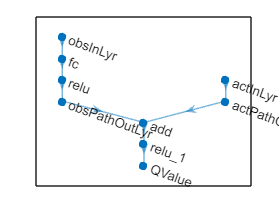


figure;
plot(criticNetwork);


critic = rlQValueFunction(criticNetwork, ...
    obsInfo,actInfo, ...
    ObservationInputNames="obsInLyr", ...
    ActionInputNames="actInLyr",...
    UseDevice="gpu");

getValue(critic, ...
    {rand(obsInfo.Dimension)}, ...
    {rand(actInfo.Dimension)})

ans = single
0.2431

actorNetwork = [
    featureInputLayer(obsInfo.Dimension(1))
    fullyConnectedLayer(3)
    tanhLayer
    fullyConnectedLayer(actInfo.Dimension(1))
    ];
actorNetwork = dlnetwork(actorNetwork);
summary(actorNetwork)

   Initialized: true

   Number of learnables: 16

   Inputs:
      1   'input'   3 features



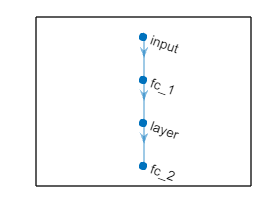


figure;
plot(actorNetwork);


actor = rlContinuousDeterministicActor(actorNetwork,obsInfo,actInfo,UseDevice="gpu");

getAction(actor,{rand(obsInfo.Dimension)})

ans = 1×1 cell array
    {[0.2906]}


agent = rlDDPGAgent(actor,critic);

agent.SampleTime = Ts;

agent.AgentOptions.TargetSmoothFactor = 1e-3;
agent.AgentOptions.DiscountFactor = 1.0;
agent.AgentOptions.MiniBatchSize = 128;
agent.AgentOptions.ExperienceBufferLength = 1e6; 

agent.AgentOptions.NoiseOptions.Variance = 0.3;
agent.AgentOptions.NoiseOptions.VarianceDecayRate = 1e-5;

agent.AgentOptions.CriticOptimizerOptions.LearnRate = 1e-03;
agent.AgentOptions.CriticOptimizerOptions.GradientThreshold = 1;
agent.AgentOptions.ActorOptimizerOptions.LearnRate = 1e-04;
agent.AgentOptions.ActorOptimizerOptions.GradientThreshold = 1;

getAction(agent,{rand(obsInfo.Dimension)})

ans = 1×1 cell array
    {[0.0897]}


trainOpts = rlTrainingOptions(...
    MaxEpisodes=10000, ...
    MaxStepsPerEpisode=ceil(Tf/Ts), ...
    ScoreAveragingWindowLength=20, ...
    Verbose=false, ...
    Plots="training-progress",...
    StopTrainingCriteria="AverageReward",...
    StopTrainingValue=2000);

% load("DDPG_waterTank_PWMDC_P1e-1_Re1500.mat", "agent");
% agent.AgentOptions.ResetExperienceBufferBeforeTraining = false;
trainingStats = train(agent, env, trainOpts);

## Evaluate a Trained DDPG Agent

rng(7129);
simOpts = rlSimulationOptions(MaxSteps=200, StopOnError="on");
simEnv = rlSimulinkEnv("rlwatertank_3", ...
        "rlwatertank_3/RL Agent", ...
        obsInfo, actInfo);
simEnv.ResetFcn = @(in)localSimResetFcn(in);

% load("waterTank_TD3_baseline2_critLR1e-3_actLR1e-4.mat", "agent");
load("waterTank_TD3_baseline2_critLR1e-3_actLR1e-4.mat", "agent_Trained_1");
experiences = sim(simEnv, agent_Trained_1, simOpts);

## Local Reset Function

function in = localResetFcn(in)
    % Randomize reference signal
    blk = sprintf("rlwatertank_3/Desired \nWater Level");
    h = 3*randn + 10;
    while h <= 0 || h >= 20
        h = 3*randn + 10;
    end
    in = setBlockParameter(in,blk,Value=num2str(h));
    
    % Randomize initial height
    h = 3*randn + 10;
    while h <= 0 || h >= 20
        h = 3*randn + 10;
    end
    blk = "rlwatertank_3/Water-Tank System/H";
    in = setBlockParameter(in,blk,InitialCondition=num2str(h));
end

function in = localSimResetFcn(in)
    % Randomize reference step signal
    blk = sprintf("rlwatertank_3/Changing Setpoint");
    h1 = 3*randn + 10;
    while h1 <= 0 || h1 >= 20
        h1 = 3*randn + 10;
    end
    h2 = 3*randn + 10;
    while h2 <= 0 || h2 >= 20 || h2 == h1
        h2 = 3*randn + 10;
    end
    in = setBlockParameter(in,blk,Before=num2str(h1));
    in = setBlockParameter(in,blk,After=num2str(h2));

    % Randomize initial height
    h = 3*randn + 10;
    while h <= 0 || h >= 20
        h = 3*randn + 10;
    end
    blk = "rlwatertank_3/Water-Tank System/H";
    in = setBlockParameter(in,blk,InitialCondition=num2str(h));
end